First, we input the ODE

global C D U N
C = 0.3; %infectiousness
D = 10 ;%infectious period
U = 0.07; %vacc. rate
N = 100000; %total pop

gamma = C*D;
mu = U*D;
y = [0, 0, 0];

S0 = 1.00; %recall that this has been non-dimensionalized, so we work in ratios.
I0 = 0.00; %start with 1% of pop infected
R0 = 0;
conditions = [S0; I0; R0];                                
span = [0 10];

[t, y] = ode45(@(t,y) odefun(t, y, gamma , mu), span, conditions);



Plot it

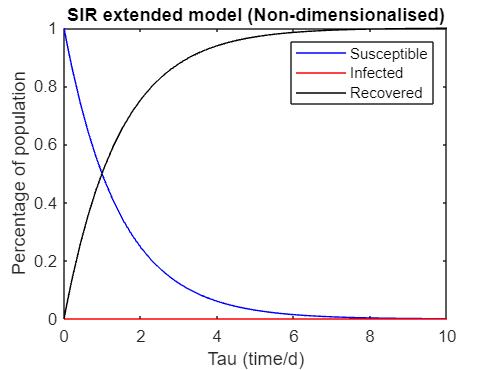

plot(t, y(:, 1), 'b', t, y(:, 2), "r", t, y(:, 3), "k")
title("SIR extended model (Non-dimensionalised)")
xlabel("Tau (time/d)")
ylabel("Percentage of population")
legend(["Susceptible", "Infected", "Recovered"])

Re-dimensionalise it

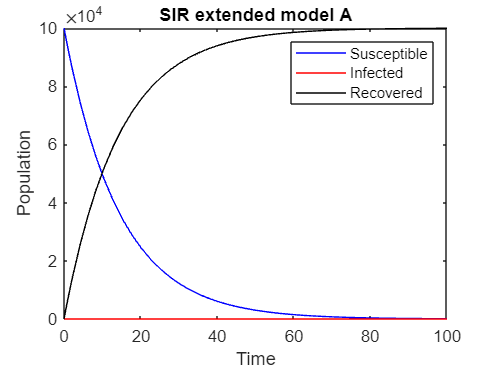

ydim = y*N ;
tdim = t*D;
plot(tdim, ydim(:, 1), 'b', tdim, ydim(:, 2), "r", tdim, ydim(:, 3), "k")
title("SIR extended model A")
xlabel("Time")
ylabel("Population")
legend(["Susceptible", "Infected", "Recovered"])

Max_I = tdim(find(ydim(:, 2) == max(ydim(:, 2))))

Max_I =          0
    0.0007
    0.0014
    0.0022
    0.0029
    0.0065
    0.0100
    0.0136
    0.0172
    0.0352


Functions

function dydt = odefun(t,y, gamma, mu)
dydt = zeros(3,1);
dydt(1) = -gamma*y(1)*y(2) -mu*y(1);
dydt(2) = gamma*y(1)*y(2) -y(2);
dydt(3) = y(2) + mu*y(1);
end